# What should the basis functions be for fitting the raw lip signals?

We model the lip fluorescence in the 500-700nm band. The script 

s_oeBloodFluorophoreLipSrch.mlx 

analyzesr 500-600 in detail.  See many notes in that livescript.

Also, have a look at the s_oeDimensionality.mlxdir analysis.

## Programming notes

**Repositories**: isetcam, isetfluorescence and oe_tongue_lip

## Initialize parameters

Different analyses are based on different wavebands.

ieInit;
wave = 500:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:20;
[T,dataDir] = oeDatabaseCreate;

## Select the fluorophores 

We create the base fluorophore emissions matrix.  It does not include blood (fluorophoresB).  Below, we sweep through different potential levels of blood optical density, checking how well the modified fluorophore matrix predicts the data samples.  Notice that the effective optical density of blood can depend on the wavelength of the excitation light.  Some lights will penetrate into the skin (substrate) more deeply than others, thus creating a longer path through the blood.

We tried many fluorophore files from the literature. These are described in in **s_oeFluorophoreEmissions.mlx**.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the lip, there is no keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

Here are notes about things we tried.

- fluorophoreNames = {'CollagenWuQu','NADH_webfluor','FADLin'};

- fluorophoreNames = {'CollagenWuQu','FADLin'}; 

- fluorophoreNames = {'CollagenWuQu','FADValdez'};

- fluorophoreNames = {'CollagenWuQu','FAD_webfluor'};

- fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'};

- fluorophoreNames = {'collagen7','elastin_webfluor','FADValdez'};

- fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor','NADH_webfluor'};

- fluorophoreNames = {'collagen1'};   % Interesting, but not great

- fluorophoreNames = {'elastin_webfluor','FADValdez'}; 

- fluorophoreNames = {'elastin_webfluor'};  

We should also try deoxygenated blood at some point.

## Create fluorophore matrix and read database

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

The logic is to read all the data for each subject at both 405 nm and 415 nm, and at all intensity levels. The data from different days are sometimes from different locations.

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);

rmse = zeros(size(subjects));
odError = zeros(numel(odLevels),numel(subjects));
ods = zeros(numel(subjects),1);    

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    lipData  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,lipData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 12.00
OD across subjects for 405/415nm 9.00
OD across subjects for 405/415nm 6.00
OD across subjects for 405/415nm 6.00


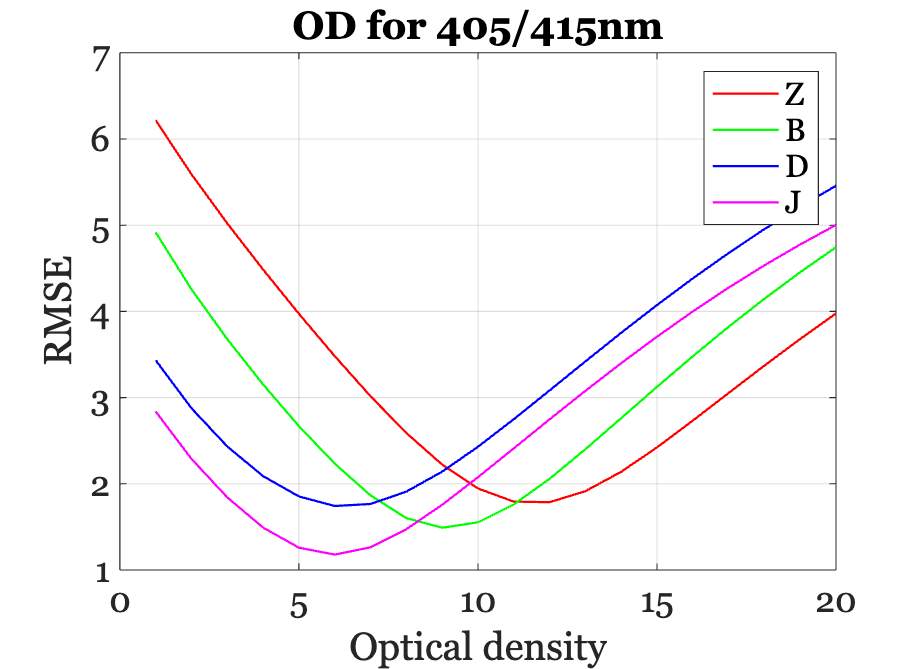


% Plot the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError);
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the estimated optical density and fit the fluorescence data

The fits with oxy applied to the collagen are great.

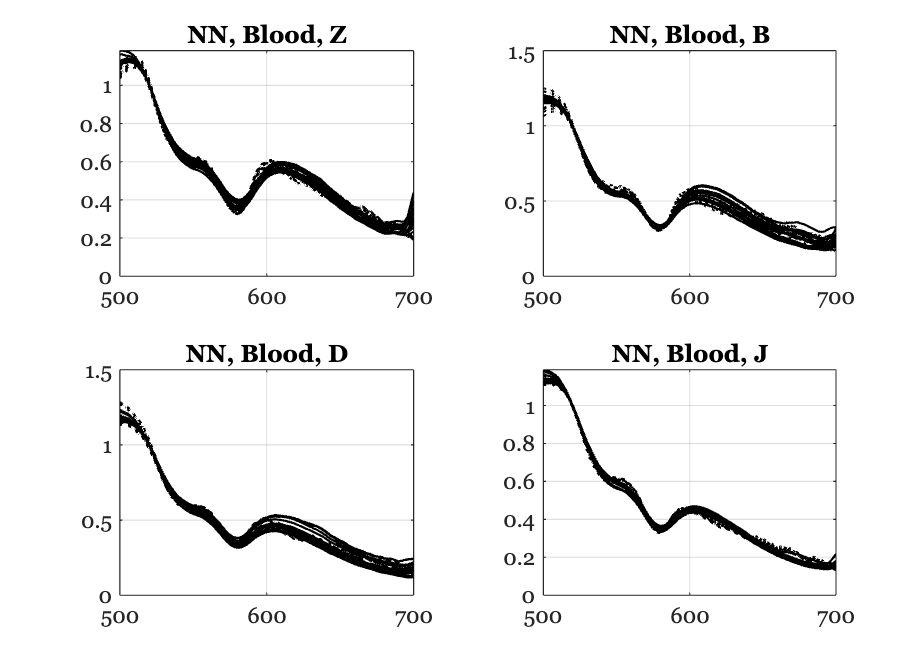

Subject Z
   16.8948   17.6706   17.2171   17.1969   16.4609   17.6714   18.0583   18.0714   17.9006   16.8347   16.9367   17.5778   18.1558   17.8456
    0.6373    0.6421    0.6305    0.6454    0.6481    0.6489    0.6485    0.6268    0.6322    0.6420    0.6398    0.6505    0.6505    0.6591

Subject B
   17.0236   15.2033   16.1461   13.6671   14.4317   17.6355   17.6523   14.7001   14.8053   16.3939   16.6239   18.1624   16.6401
    0.5148    0.5433    0.5178    0.5900    0.5667    0.4992    0.5010    0.5686    0.5666    0.5179    0.5160    0.4902    0.5130

Subject D
   12.2678   12.3073   12.4848   14.4620   14.6171   11.9692   12.2972   13.2136   12.4474   14.4875   13.7120   12.6588   12.9923   12.7923
    0.4884    0.4831    0.4812    0.4579    0.4502    0.5131    0.5040    0.4719    0.4979    0.4403    0.4709    0.4927    0.4779    0.4803

Subject J
   12.6301   12.2410   12.2374   11.4644   11.4828   11.3855   11.3455   11.6195   11.4383   11.9263   11.9201   11.8799   11.9183 


ieFigure;
tiledlayout(2,2);

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);

    lipData = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    [fluorophores,fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);
    
    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

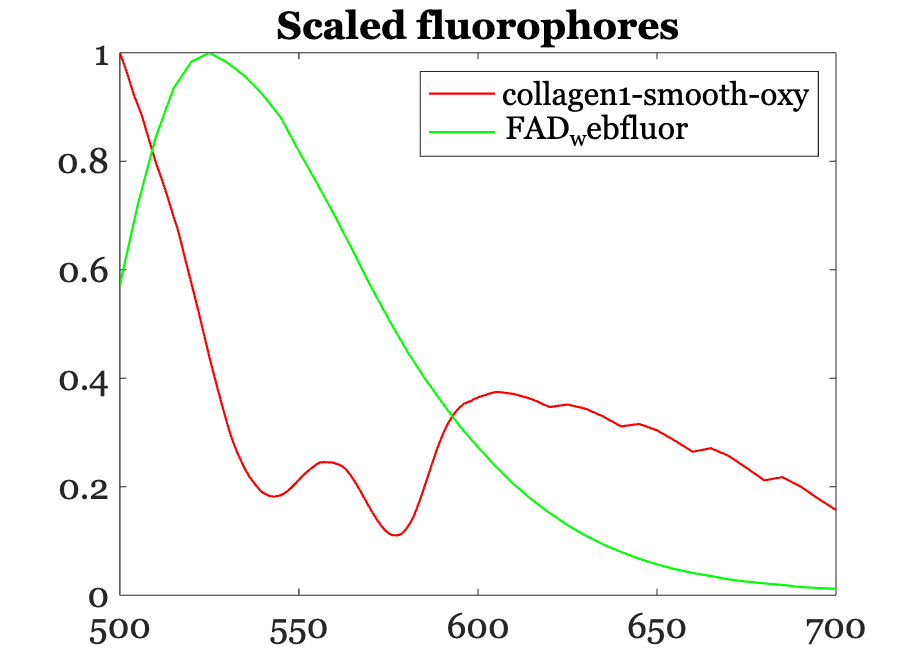


ieFigure; 
mx = max(fluorophores);
plot(wave,fluorophores*diag(1./mx));
title('Scaled fluorophores');
legend(fluorophoreNames);

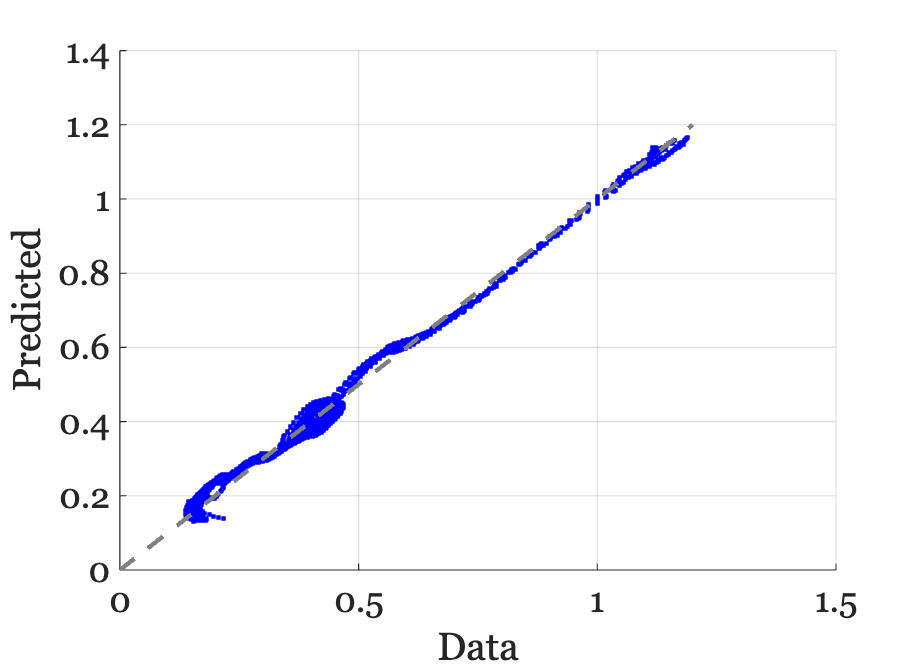


ieFigure;
tmp = fluorophores*wgtsNN;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');

## Create 450 nm blood optical density levels

The 450 nm light OD seems to be a bit different, which we explain by saying this wavelength penetrates a bit deeper into the skin.  This makes us wonder whether we need some deoxygenated blood included.

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','lip',...
        'e wave',450);
    lipData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,lipData,wave,odLevels);
end
fprintf('OD across subjects for 450nm %.2f\n',ods);

OD across subjects for 450nm 17.00
OD across subjects for 450nm 18.00
OD across subjects for 450nm 11.00
OD across subjects for 450nm 13.00


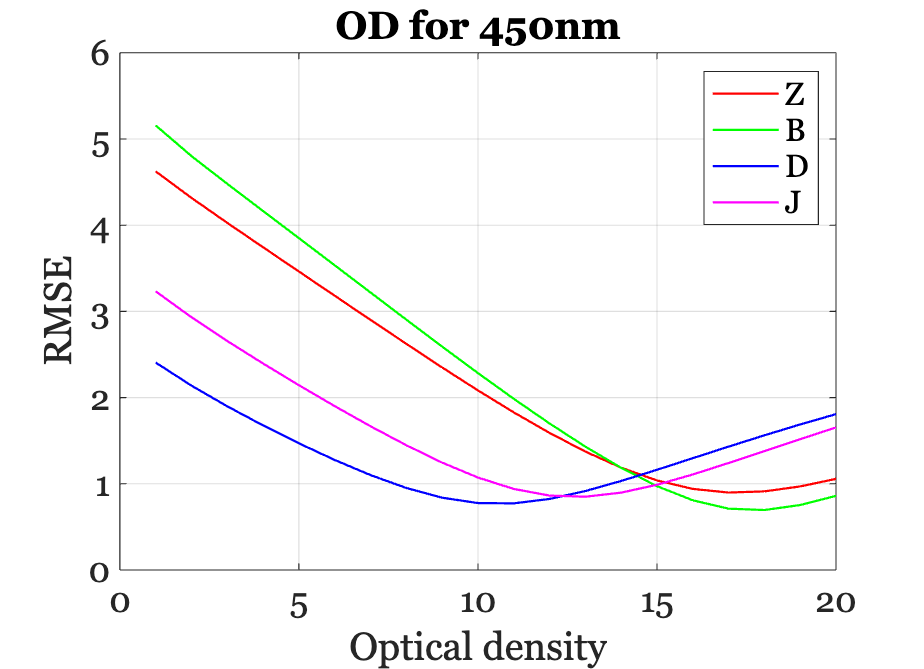

ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');  

## 450 nm excitation light

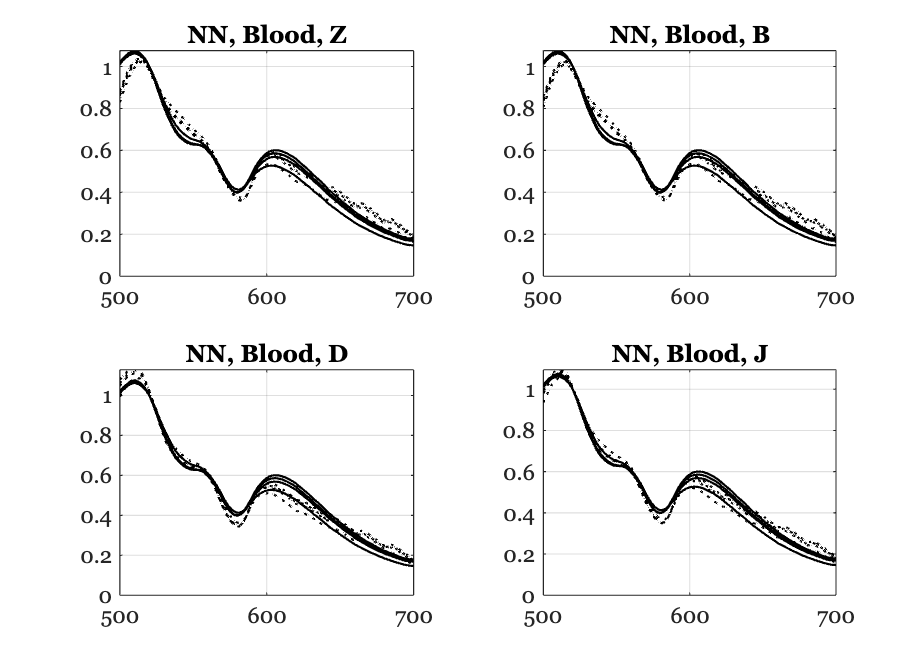

Subject Z
   15.9250   16.4227   14.0097   17.0531
    0.7962    0.7912    0.8257    0.7842

Subject B
   16.0102   16.5168   14.0711   17.1573
    0.8103    0.8056    0.8382    0.7991

Subject D
   14.8554   15.2768   13.1572   15.8211
    0.6785    0.6707    0.7202    0.6600

Subject J
   15.3300   15.7814   13.5444   16.3593
    0.7251    0.7183    0.7621    0.7090



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);

    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end


disp(fluorophoreNames'); 

    {'collagen1-smooth-oxy'}
    {'FAD_webfluor'        }



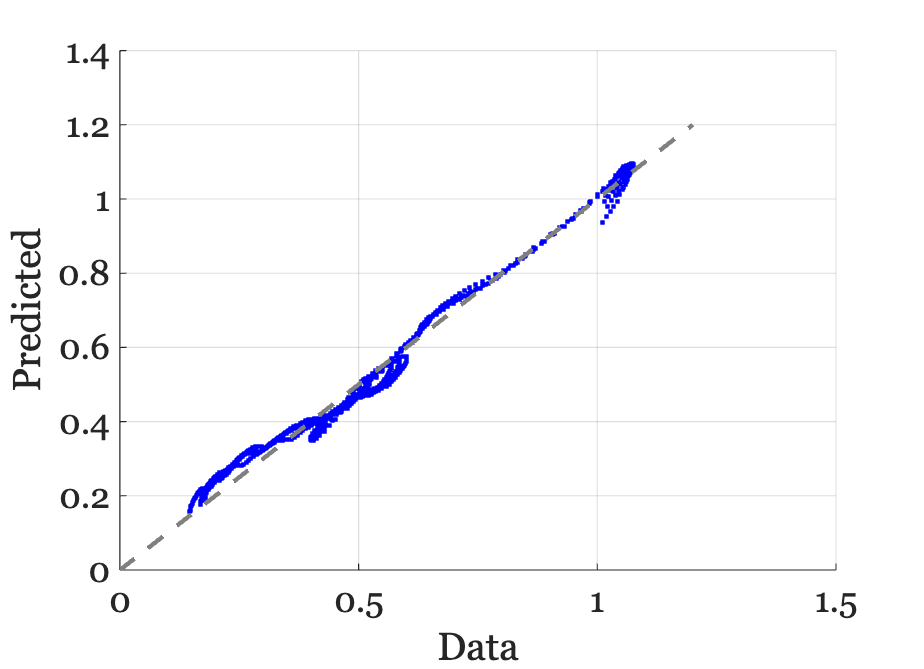


ieFigure;
tmp = fluorophores*wgtsNN;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');

## Once more with deoxy

There is no real value add in this case for putting in a lot or a little deoxy.  We tried OD of 5, 30, and 60.  We could see the weights changing but not the RMSE.  Two of the subjects don't use the deoxy at all in any case.

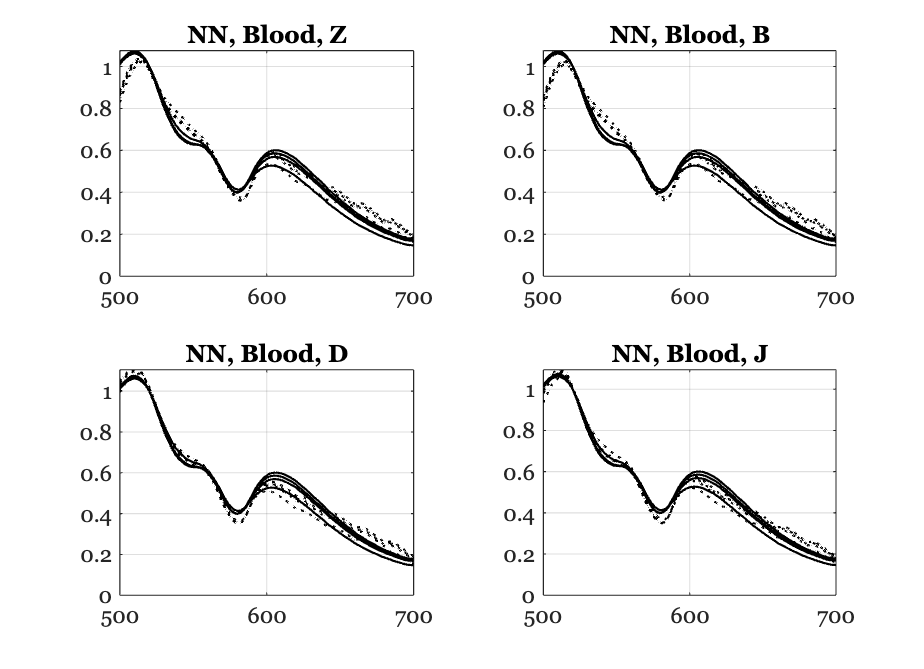

Subject Z
   15.9250   16.4227   14.0097   17.0531
    0.7962    0.7912    0.8257    0.7842
         0         0         0         0

Subject B
   16.0102   16.5168   14.0711   17.1573
    0.8103    0.8056    0.8382    0.7991
         0         0         0         0

Subject D
   13.2314   13.1239   13.1572   12.7843
    0.6937    0.6909    0.7202    0.6885
    2.1522    2.8531         0    4.0246

Subject J
   15.3300   15.7814   13.5444   16.3593
    0.7251    0.7183    0.7621    0.7090
         0         0         0         0



deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 8;
%{
ieFigure;
plot(wave,deoxyblood.transmittance,'b-',wave,oxyblood.transmittance,'r-');
%}

ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood, ...
        'deoxy',deoxyblood);

    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);

    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end


disp(fluorophoreNames'); 

    {'collagen1-smooth-oxy'  }
    {'FAD_webfluor'          }
    {'collagen1-smooth-deoxy'}



ieFigure;
tmp = fluorophores*wgtsNN;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');